# TP1 Algèbre 

*Le compte rendu est à rédiger directement dans ce document avec votre code que vous pourrez executer à partir de ce fichier section par section.*

*Il vous est demandé de montrer les résultats, de les analyser et les interpréter tout en répondant aux questions. Nous jugerons vos capacités à comprendre et interpréter mathématiquement les réalisations. *

## 1 - Affichage de vecteurs

#### 1.1 Repère orthonormé 2D

Affichez les deux vecteurs unitaires i et j du repère orthonormé dans une figure disposant d’une grille et dont les limites seront [- 2,+2] en x et en y (fig.1).  

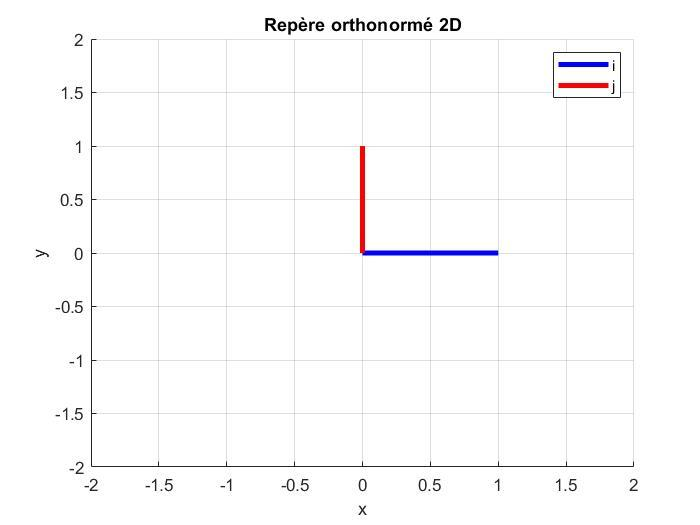

Figure 1 - Repère orthonormé 2D

%*******************************************************************************
% écrire ici le code qui trace le repère orthonormé 2D
%*******************************************************************************




#### 1.2 Repère orthonormé 3D

Affichez les trois vecteurs unitaires i, j et k du repère orthonormé (fig.2). On tilisera la fonction plot3 (plot en 3D)  

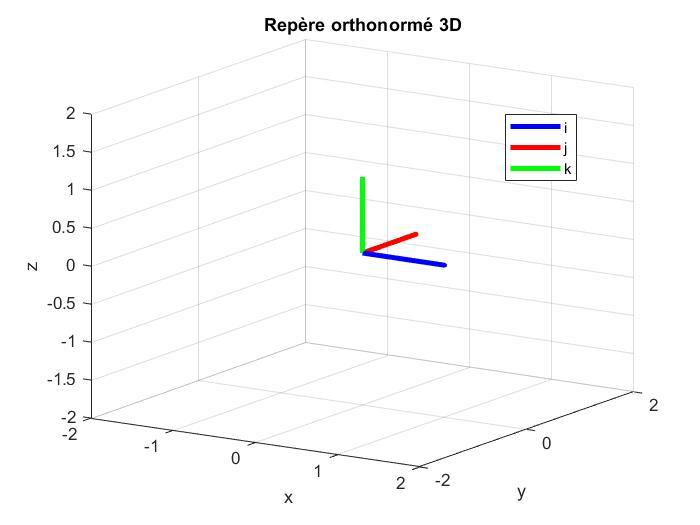

Figure 2 - Repère orthonormé 3D

%******************************************************************************
% écrire ici le code qui trace le repère orthonormé 3D
%******************************************************************************




#### 1.3 Triangle et carré

Dessinez un triangle centré en 0, en affichant la grille. Sur un deuxième graphique dessinez un carré avec des étoiles aux sommets (fig.3) . La fonction ***subplot*** de Matlab nous permet de faire plusqieurs graphiques sur une même fenêtre. Son utilisation est détaillée dans la documentation Matlab.

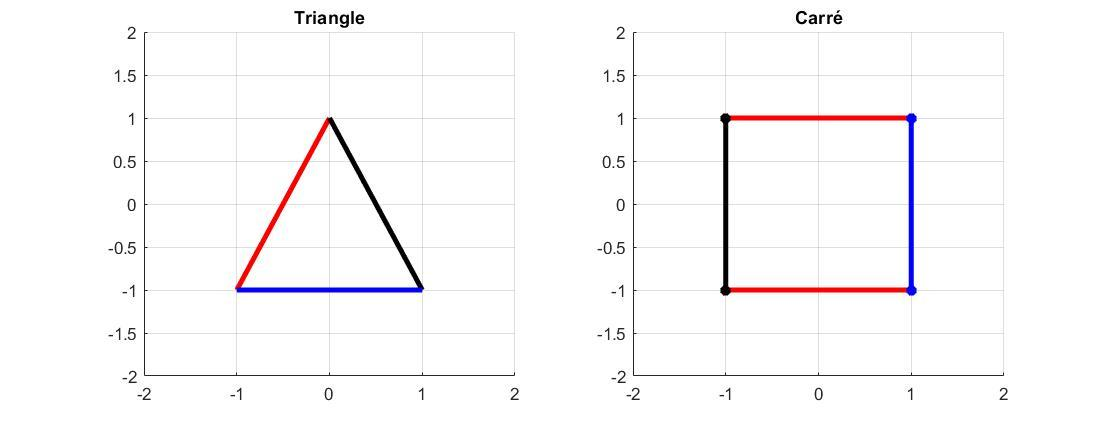

Figure 3 : Triangle et carré

%*******************************************************************************
% écrire ici le code qui trace le triangle et le carré sur une même figure
%******************************************************************************
figure()
% le subplot ci dessous permet de diviser la figure en 1 ligne, 2 colonnes et de 
% sélectionner le premier graphique pour le tracé
subplot(1,2,1) 
%-----------------------------------------
% écrire ici le code qui trace le triangle 





%------------------------------------------
%on sélectionne ensuite le second graphique
subplot(1,2,2) 
%-----------------------------------------
% écrire ici le code qui trace le carré 





%------------------------------------------

## 2- Calcul de l'image d'un vecteur

### 2.1 Transformation linéaire

On souhaite pouvoir afficher un vecteur et son image par l’application linéaire décrite par la matrice suivante :  


$$M=\left\lbrack \begin{array}{cc}
\frac{5}{4} & 0\\
-\frac{1}{2} & \frac{3}{4}
\end{array}\right\rbrack$$


Ecrire une fonction ***transformation*** qui admet en entrée la matrice M, ainsi qu'un vecteur donné que l’on appellera X. Elle calcule et retourne la transformée Y telle que Y = M * X. La fonction affichera sur une figure le vecteur X de départ en bleu et le vecteur d’arrivée Y en rouge. 

*Note: On écrira la fonction à la fin de ce document, dans la section ****Fonctions**** et non pas dans un fichier à part comme on avait fait au TP0 afin de simplifier le rendu et n'avoir qu'un seul fichier à déposer à la fin de la séance.*

Une fois que avez implémenté la fonction, testez le programme ci-dessous avec quelques vecteurs de votre choix  

%*******************************************************************************
% écrire ici le code qui appelle la fonction transformation avec des
% vecteurs de votres choix
%******************************************************************************
%on définit le vecteur X
X = [1;1];
%--------------------------------------------------
% rajoutez ci- dessous la définition de la matrice M



% on appelle ensuite la fonction transformation
Y= transformation(M,X);

%--------------------------------------------------
% Définir d'autres vecteurs X et appeler la fonction




Utilisez votre code  pour répondre aux questions suivantes :

a) Le vecteur [1 ;1] est-il un vecteur propre de M ? pourquoi ?

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

 b) Le vecteur [0 ;1] est-il un vecteur propre de M ? pourquoi ?  

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

### 2.2 Transformation linéaire : cas particulier

On propose maintenant de modifier la matrice de transformation. Au lieu de M définie précédemment, on souahite utiliser: 


$$R=\left\lbrack \begin{array}{cc}
\cos \left(\theta \right) & -\sin \left(\theta \right)\\
\sin \left(\theta \right)\; & \cos \left(\theta \right)
\end{array}\right\rbrack$$


Testez votre programme de transformation avec différentes valeurs de  $\theta \;$

%*******************************************************************************
% écrire ici le code qui effectue les transformations par la matrice R
%******************************************************************************




Faites le calcul sur papier pour les vecteurs unitaires avec $\theta \;$quelconque (vous pouvez ensuite insérer une photo de vos calculs dans ce document ou écrire directement les équations ici).

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

En vous basant sur les observations géométriques ainsi que sur votre calcul, déduire ce que représente la matrice R ?  

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

### 2.3 Transformation linéaire en 3D

On considère maintenant la matrice R2 :


$$\textrm{R2}=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & R\left(1,:\right) & \\
0 & R\left(2,:\right) & 
\end{array}\right\rbrack$$


Testez, avec différentes valuers de $\theta \;$,  la transfromation de vecterus en 3D.

%*******************************************************************************
% écrire ici le code qui effectue les transformations par la matrice R2
%******************************************************************************





Que représente la matrice R2 ? Expliquez

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

### 2.4 Transformations successives

En prenant le vecteur $\textrm{V1}=\left\lbrack 1;0\right\rbrack \;\textrm{et}\;\;\theta =\frac{\pi }{10}$ , calculez $\textrm{V1}=R*\textrm{V1}$ 20 fois en utilisant une boucle *for *et tracez les 20 vecteurs calculés.

%*******************************************************************************
% écrire ici la boucle qui calcule et affiche les 20 vecteurs
%******************************************************************************






## 3- Chiffrement polygraphique

Les méthodes de chiffrement dites polygraphiques procèdent au chiffrement d'un message par paquets de *n *lettres en utilisant une clé de n nombres. 

Pour comprendre le principe, prenons le cas simple où n=2, on parle alors de chiffrement diagraphique. 

On associe d'abord à chaque lettre de l'alphabet, un code numérique, qui est, par exemple, un nombre compris entre 0 et 25 pour les 26 lettres majuscules :  

On se donne ensuite quatre nombres (a, b, c, d), bien choisis, qui constitueront la "clé" du chiffrement. 

Soit $x_1$ et $x_2$ les codes numériques associés aux deux premières lettres du mot à chiffrer. On en déduit les codes $y_1$ et $y_2$ des deux lettres correspondantes dans le mot chiffré par l'opération suivante :  


$$\left\lbrace \begin{array}{ll}
y_{1\;} ={\textrm{ax}}_1 +{\textrm{bx}}_2  & \\
y_2 ={\textrm{cx}}_1 +{\textrm{dx}}_2  & 
\end{array}\right.$$


Si les codes $y_1$ et $y_2$ ainsi obtenus ne sont pas compris entre 0 et 25, on les remplace par leur valeur  ${y^{\prime } }_1$ et ${y^{\prime } }_2$ modulo 26, c'est-à-dire que l'on soustrait autant de fois que nécessaire la valeur 26 au code y s'il est positif, ou on lui ajoute autant de fois que nécessaire la valeur 26 s'il est négatif, afin d'obtenir un nombre y' compris entre 0 et 25.  Autrement dit on le remplace par le reste de sa division par 26.

Il ne reste plus qu'à chercher dans la table des codes à quelles lettres correspondent ces deux codes y' finaux, puis de recommencer la procédure pour tous les autres "paquets" de deux lettres suivants du mot à chiffrer, et ainsi obtenir le mot complet chiffré.  

Exemple: chiffrement du mot "**TP**" avec la clé (3,-2,-1,1)  

- On code les lettres du mot à l'aide de la table de correspondance : T => 19 = *x*1 et P => 15 = *x*2  

- On chiffre ces deux codes :  $\left\lbrace \begin{array}{ll}
y_{1\;} =\;3*19\;-\;2*15=27 & \\
y_2 =-19+15=-4 & 
\end{array}\right.$

On remarque que 27 n'est pas un code "valide" (non compris entre 0 et 25), donc on le ramène à 1 en lui retranchant 26. De la même façon on ramène le -4 à 22 en lui rajoutant 26  

Le mot "**TP**" chiffré est donc finalement décrit par les codes $y_1^{\prime } =1$et $y_2^{\prime } =22$, soit le mot "**BW"**  

### 3.1 Formalisation

a) Écrivez sous forme matricielle l'opération de chiffrement, permettant de passer des codes de départs $x_1$ et $x_2$ aux codes chiffrés$y_1$ et $y_2$. On ne tiendra pas compte des éventuels modulo 26 dans cette écriture.

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

b) En déduire l'opération inverse de déchiffrement sous forme matricielle. Quelle condition nécessaire doivent respecter les nombres choisis pour la clé afin que le décryptage soit possible ?

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

c ) Chiffrez le mot "POLYTECH" avec la clé (2,3,1,1). Remplissez pour cela le tableau ci-dessous en faisant le calcul matriciel sous Matlab. Pour le calcul du modulo vous pouvez utiliser la fonction ***mod*** de Matlab.

 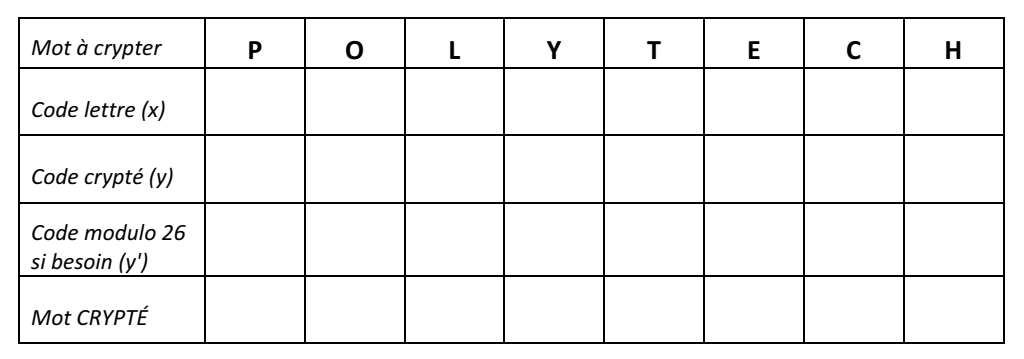

*************************************************************************************************************** 

***VOTRE REPONSE ICI ***

%*******************************************************************************
% écrire ici un code qui calcule y' étant donné x pour vous aider à remplir
% le tableau
%******************************************************************************
% on définit x
x1= 19;  % entrez un nombre entre 0 et 25
x2= 15;  % entrez un nombre entre 0 et 25

x= [x1; x2];

%-----------------------------------------------------------
% calculez y' en faisant l'opération matricielle et le modulo




%-----------------------------------------------------------

d) Décryptez le mot "KFCKIP" avec la même clé qu'à la question précédente. Remplissez pour cela un tableau similaire à celui utilisé pour le cryptage, en explicitant de même les opérations à faire sur chaque ligne.  

*************************************************************************************************************** 

***VOTRE REPONSE ICI ***

%*******************************************************************************
% écrire ici un code qui remonte à x étant donné y pour vous aider à
% décrypter
%******************************************************************************






### 3.2 Chiffrer un code

Écrivez (dans la section **Fonctions**) une fonction ***chiffrerCode*** qui admet en entrée un vecteur de codes lettres (les x) et une matrice "clé", et renvoie le vecteur des y' correspondants.

Une fois la fonction implémentée, testez-la avec la clé (2,3,1,1) et le mot "POLYTECH" en code lettre (programme ci-dessous)

%*******************************************************************************
% code qui teste votre fonction chiffrer
%******************************************************************************
x = [15,14,11,24,19,4,2,7];
cle = [2 3 ; 1 1];
y = chiffrerCode(x,cle);
disp(y)

  Si votre fonciton est correcte, vous devriez voir  s'afficher :  20   3   16   9   24   23   25   9  

### 3.3 Déchiffrer un code

Écrivez (dans la section **Fonctions**) une fonction ***dechiffrerCode*** qui admet en entrée un vecteur de codes chiffrés (les y') et une matrice "clé", et renvoie le vecteur des codes x correspondants.

Une fois la fonction implémentée, testez-la avec la clé (2,3,1,1) et le code obtenu à la question 3.2 (programme ci-dessous)

%*******************************************************************************
% code qui teste votre fonction chiffrer
%******************************************************************************
y = [20,3,16,9,24,23,25,9];
cle = [2 3 ; 1 1];
x = dechiffrerCode(y,cle);
disp(x)


  Si votre fonciton est correcte, vous devriez voir  s'afficher :  15  14  11  24  19  4  2  7 

### 3.4 Chiffrer et déchiffrer des mots en toutes lettres

Ecrivez (dans la section **Fonctions**) les fonctions ***chiffrer*** et ***déchiffrer ***de sorte à admettre le mot en toute lettre directement en argument et renvoyer le mot chiffré ou déchiffré.  

Une fois vos fonctions implémentées, testez-les avec la clé (2,3,1,1) et le mot POLYTECH

%*******************************************************************************
% code qui teste vos fonctions chiffrer et dechiffrer
%******************************************************************************
mot = 'POLYTECH'
cle = [2 3 ; 1 1];
s = chiffrer(mot,cle);
fprintf('le mot %s est chiffré en tant que %s \n', mot, s)

ss = dechiffrer(s,cle);
fprintf('en déchiffrant on retrouve bien %s \n',ss)

Après déchiffrement vous devriez retrouver le mot POLYTECH.

Déchiffrer le mot mystère KFCKIP  

motChiffre = 'KFCKIP'
motMystere = dechiffrer(motChiffre,cle);
fprintf('le mot mystère est %s \n',motMystere)

### 3.4 Chiffrer et déchiffrer avec des clés d'ordre plus élevé

Afin de rendre le chiffrement plus complexe on peut utiliser des matrices clés de dimensions 3, 4 ou plus. Définissez une matrice de chiffrement de 3x3 telle que [1 2 4 ; 1 1 2 ; 0 1 1 ]. Testez-la avec les fonctions ***chiffrer*** et ***dechiffrer*** programmées précédemment. Si vos fonctions sont bien définies aucune modification du code est nécessaire pour passer à des dimensions supérieures.

%*******************************************************************************
% écrire ici un code qui teste vos fonctions chiffrer et dechiffrer avec une 
% clé 3x3
%******************************************************************************







## Les Fonctions

function Y = transformation (M,X)
%*******************************************************************************
% écrire ici le code qui transforme X en Y tel que Y = M*X et trace les
% deux vecteurs
%******************************************************************************



end

function crypt = chiffrerCode (x, cle)
%*******************************************************************************
% écrire ici le code qui chiffre le vecteur x avec la cle et retourne crypt
% (crypt c'est les y' après calcul du modulo)
%******************************************************************************

%vecteur que vous devez retourner
crypt=[];

% Astuce ---------------------------------------------------------------------- 
% On pourrait utiliser la fonction reshape pour réarranger le vecteur d'entrée 
% en paquets et pouvoir traiter le mot paquet par paquet.
% Par exemple reshape(vect, 2, []) permet de  transformer le vecteur colonne vect 
% en une matrice de 2 x nombre de paquets

%-----------------------------------------------------------------------------
% commencez pas appeler reshape correctement pour mettre en forme votre vecteur x





%-----------------------------------------------------------------------------
% calculez ensuite le code y' et stockez le dans crypt
% A priori aucune boucle n'est nécessaire. 




%-----------------------------------------------------------------------------
% refaire un reshape à la fin de sorte que crypt ait les mêmes dimensions
% que x 



end

function decrypt = dechiffrerCode (y, cle)
%*******************************************************************************
% écrire ici le code qui déchiffre le vecteur y avec la cle et retourne decrypt
% (decrypt correspond au vecteur x)
%******************************************************************************
%vecteur que vous devez retourner
decrypt=[];

%-----------------------------------------------------------------------------
% Utilisez la fonction chiffrerCode avec la bonne clé pour déchiffrer




end

function crypt = chiffrer(mot, cle)
%*******************************************************************************
% écrire ici le code qui chiffre un mot avec la cle donnée
%******************************************************************************

%-----------------------------------------------------------------------------
% On transforme d'abord le vecteur mot en un vecteur code pour pouvoir
% utiliser chiffrerCode définie précédemment
% Une façon simple pour faire la correspondance entre lettre et code 
% serait de définir une chaine de % caractère
alphabet = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ';


%-----------------------------------------------------------------------------
% on utilise ensuite strfind pour repérer la position de la lettre recherchée.
% Par exemple: 
% strfind(alphabet, 'C') 
% nous renvoie 3 (attention le code de C est 2)
% écrire ici le code qui transforme le vecteur lettre x en un vecteur code





%-----------------------------------------------------------------------------
% appelez la fonction chiffrerCode avec le vecteur code obtenu à l'étape
% précédente pour calculer y




%-----------------------------------------------------------------------------
% à partir du vecteur y remontez au mot 
% Par exemple 
% alphabet ([1;2;3])
% renvoie ABC


end


function crypt = dechiffrer(mot, cle)
%*******************************************************************************
% écrire ici le code qui dechiffre un mot avec la cle donnée en utilisant
% la fonction chiffrer précédemment définie
%******************************************************************************




end